% none model parameters
tic
x=1;
x1 = 1;

sensitivity=table();
specificity=table();
datestr(now, 'dd/mm/yy-HH:MM')

ans = '07/11/23-09:43'

sensitivity1=table();
specificity1=table();
accuracytb=table();
precision=table();

%rootDir = "C:\Users\bhavana.maradani\Desktop\Feb_6_2023\stoneID_classification";
rootDir = "D:\April_17_2023\P12484-master-stoneID_classification\stoneID_classification";
%for integra = [1 50 75 150 250 350]
integra = 50

integra = 50

dslocation = fullfile(rootDir, "data", "XL-11-02");
% datadescription = '23E'; 
% distanceRange = 'ZeroToFour';
[dataAll, dataSummary] = ops.import.readCSV( dslocation, IncludeSubfolders=true);

% Add all folders to path
addpath(genpath(rootDir))
dataAll.Response = dataAll.TargetType;
size(dataAll)

ans =        10125        2059


% consider only current integration time
dataAll(dataAll.IntegrationTimeUsed ~= string(integra) ,:) = [];
currentFilter = dataAll.ResponseRegression >= 2 & dataAll.ResponseRegression < 5;
dataAll = dataAll(currentFilter, :);
size(dataAll)

ans =          375        2059


data = dataAll 

data = 375×2059 table
    Feature 1    Feature 2    Feature 3    Feature 4    Feature 5    Feature 6    Feature 7    Feature 8    Feature 9    Feature 10    Feature 11    Feature 12    Feature 13    Feature 14    Feature 15    Feature 16    Feature 17    Feature 18    Feature 19    Feature 20    Feature 21    Feature 22    Feature 23    Feature 24    Feature 25    Feature 26    Feature 27    Feature 28    Feature 29    Feature 30    Feature 31    Feature 32

% predictorNames = string(dataAll.Properties.VariableNames(...
%      contains(dataAll.Properties.VariableNames, "Feature")))';
% data = dataAll(:,[predictorNames; "Response"]);
% data.Response(ismember(data.Response, ["Access Sheath 13 15"...
%    "Endoscope", "BEGO"])) = "Non-stone";
% data.Response(ismember(dataModel1.Response, [ "COM", "UA"])) = "Stone";

dataModel1 = data;
dataModel1.Response(ismember(dataModel1.Response, ["Access Sheath 13 15", ...
    "Endoscope", "Tissue-Calyx", "Tissue-Ureter", "BEGO", "Guidewire"])) = "Non-stone";
dataModel1.Response(ismember(dataModel1.Response, [ "COM", "UA"])) = "Stone";


dataModel2 = data;

isNonStone = ismember(dataModel2.Response, ["Access Sheath 13 15", ...
    "Endoscope", "BEGO","Tissue-Calyx", "Tissue-Ureter", "Guidewire"]);
dataModel2(isNonStone,:) = [];


% load the saved model for 350 integration time
obj = load('D:\April_17_2023\P12484-master-stoneID_classification\stoneID_classification\Prestine fibers\Cleaved@0mm\LEDABOFF_50AvgcleavedBB@0mmTwoToFour11_07_2023_09_35.mat');

model1 = obj.model1

model1 = struct with fields:
      Results: [1×1 struct]
         Info: [1×12 table]
      Session: [1×1 experiment.Classification]
    dataTrain: [930×2049 table]
     dataTest: [225×2049 table]


model2 = obj.model2

model2 = struct with fields:
      Results: [1×1 struct]
         Info: [1×12 table]
      Session: [1×1 experiment.Classification]
     dataTest: [75×2049 table]
    dataTrain: [300×2049 table]


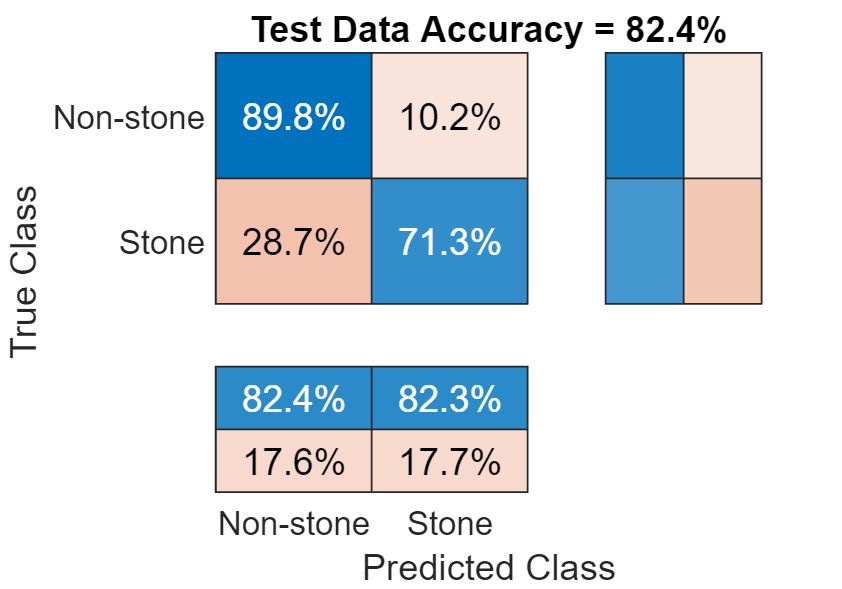

[cm, result1] = CMprediction(model1, dataModel1(:, [1:2048, 2059]));

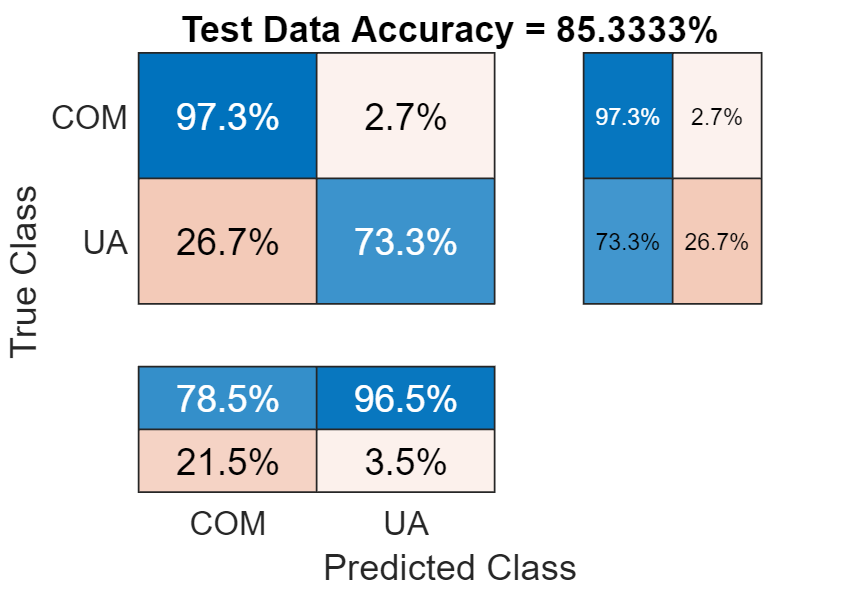

[cm2, result] = CMprediction(model2, dataModel2(:, [1:2048, 2059]));

beep on
beep
matrix1=cm.NormalizedValues;
labels1=string(cm.ClassLabels);
statsmatix1= statsOfMeasure(matrix1,1);

stats = 9×4 table
          name               classes          macroAVG    microAVG
    ________________    __________________    ________    ________

    "true_positive"     0.89778    0.71333    0.80556     0.80556 
    "false_positive"    0.28667    0.10222    0.19444     0.19444 
    "false_negative"    0.10222    0.28667    0.19444     0.19444 
    "true_negative"     0.71333    0.89778    0.80556     0.80556 
    "precision"         0.75797    0.87466    0.81632     0.80556 
    "sensitivity"       0.89778    0.71333    0.80556     0.80556 
    "specificity"       0.71333    0.89778    0.80556     0.80556 
    "accuracy"          0.80556    0.80556    0.80556     0.80556 
    "F-measure"         0.82197     0.7858    0.80389     0.80556 



if x1==1  

sensitivity1{x1,:}= statsmatix1.classes(6,:);
specificity1{x1,:}= statsmatix1.classes(7,:);
sensitivity1.Properties.VariableNames =labels1;
specificity1.Properties.VariableNames =labels1;

else 

sensitivity1{x1,:}= statsmatix1.classes(6,:);
specificity1{x1,:}= statsmatix1.classes(7,:);

end 
x1=x1+1;

matrix=cm2.NormalizedValues;
labels=string(cm2.ClassLabels);
statsmatix= statsOfMeasure(matrix,1);

stats = 9×4 table
          name                classes           macroAVG    microAVG
    ________________    ____________________    ________    ________

    "true_positive"      0.97333     0.73333    0.85333     0.85333 
    "false_positive"     0.26667    0.026667    0.14667     0.14667 
    "false_negative"    0.026667     0.26667    0.14667     0.14667 
    "true_negative"      0.73333     0.97333    0.85333     0.85333 
    "precision"          0.78495     0.96491    0.87493     0.85333 
    "sensitivity"        0.97333     0.73333    0.85333     0.85333 
    "specificity"        0.73333     0.97333    0.85333     0.85333 
    "accuracy"           0.85333     0.85333    0.85333     0.85333 
    "F-measure"          0.86905     0.83333    0.85119     0.85333 



if x==1  

sensitivity{x,:}= statsmatix.classes(6,:);
specificity{x,:}= statsmatix.classes(7,:);
sensitivity.Properties.VariableNames =labels;
specificity.Properties.VariableNames =labels;

else 

sensitivity{x,:}= statsmatix.classes(6,:);
specificity{x,:}= statsmatix.classes(7,:);

end 
x=x+1;
%end
sensitivity1

sensitivity1 = 1×2 table
    Non-stone     Stone 
    _________    _______

     0.89778     0.71333


specificity1

specificity1 = 1×2 table
    Non-stone     Stone 
    _________    _______

     0.71333     0.89778



sensitivity

sensitivity = 1×2 table
      COM        UA   
    _______    _______

    0.97333    0.73333


specificity

specificity = 1×2 table
      COM        UA   
    _______    _______

    0.73333    0.97333


datestr(now, 'dd/mm/yy-HH:MM')

ans = '07/11/23-09:43'

%toc
